# Problema 2

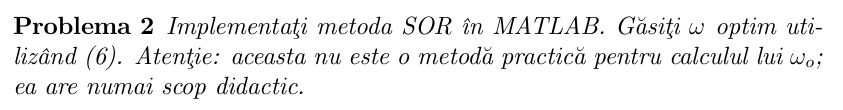

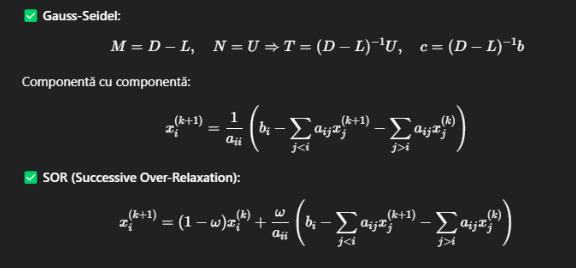

### Formula optimizare omega: $\omega_{\textrm{opt}} =\frac{2}{1+\sqrt{1-\rho^2 }}$

ρ este raza spectrală (adică cea mai mare valoare absolută a valorilor proprii) a matricei de iterație Jacobi Tj = masoara cat de repede "converg" metodele iterative. Formula de mai sus optimizraza omega pentrua obtine o raza spectrala minima in SOR. Daca omega este egala cu 1, algoritmul este la fel ca metoda de baza, Gauss-Seidel

% Rezolvam  sistemul Ax=b
% Gauss-Seidel adauga un factor de relaxare w

function [solutie, nr_iteratii] = metoda_sor(A, b, w, tol, iter_max)
    n = length(b);
    x = zeros(n, 1);             % aproximatie initiala cu valori de 0
    nr_iteratii = 0;

    while nr_iteratii < iter_max
        x_vechi = x;             % memorăm soluția anterioară

        for i = 1:n
            % produsul scalar, excluzand x(i)
            s = A(i,:) * x - A(i,i) * x(i);   

            % Aplicam formula SOR
            x(i) = (1 - w) * x_vechi(i) + w * (b(i) - s) / A(i,i);
        end

        nr_iteratii = nr_iteratii + 1;

        % ca si la p b anterioara, acesta este pragul de stop 
        % (cat de aproape este de rezultatul real)
        if norm(x - x_vechi, inf) < tol
            break;
        end
    end

    solutie = x;
end
function w_opt = calculeaza_omega_opt(A)
    % Descompunem A in componentele D,Lsi U (diagonala, inferioara, superioara)
    D = diag(diag(A));
    L = tril(A, -1);
    U = triu(A, 1);

    % Matricea de iterateie pentru Jacobi
    T = -inv(D) * (L + U);

    % Raza spectrala
    p = max(abs(eig(T)));

    % Conditie de convergenta in functie de raza spectrala
    if p >= 1
        warning("Jacobi nu converge, ω optim nu poate fi estimat.");
        w_opt = NaN;
    else
        % Formula teoretica pentru w optim
        w_opt = 2 / (1 + sqrt(1 - p^2));
    end
end
function validare = este_solutia_buna(A, b, x)
    eroare = norm(A * x - b, inf);
    validare = eroare < 1e-6;

    if validare
        disp('Soluția este corectă (Ax ≈ b).');
    else
        disp('Soluția NU este validă.');
    end
end

A = [4 -1 0 0;
    -1 4 -1 0;
     0 -1 4 -1;
     0 0 -1 3];

b = [15; 10; 10; 10];
tol = 1e-12;
maxim = 1000;

% Test fără optimizare (w = 1.9)
w = 1.9;
[x1, i1] = metoda_sor(A, b, w, tol, maxim);
disp('Rezultat SOR cu ω = 1.9:');

Rezultat SOR cu ω = 1.9:


disp(x1'); fprintf('Iterații: %d\n', i1);

    5.0000    5.0000    5.0000    5.0000

Iterații: 287


este_solutia_buna(A, b, x1);

Soluția este corectă (Ax ≈ b).



% Test cu ω = 1 (Gauss-Seidel)
[x2, i2] = metoda_sor(A, b, 1, tol, maxim);
disp('Rezultat Gauss-Seidel (ω = 1):');

Rezultat Gauss-Seidel (ω = 1):


disp(x2'); fprintf('Iterații: %d\n', i2);

    5.0000    5.0000    5.0000    5.0000

Iterații: 19


este_solutia_buna(A, b, x2);

Soluția este corectă (Ax ≈ b).



% Test cu ω optim calculat
w_opt = calculeaza_omega_opt(A);
[x3, i3] = metoda_sor(A, b, w_opt, tol, maxim);
disp('Rezultat SOR cu ω optim:');

Rezultat SOR cu ω optim:


disp(x3'); fprintf('Iterații: %d\nω optim: %.6f\n', i3, w_opt);

    5.0000    5.0000    5.0000    5.0000

Iterații: 13
ω optim: 1.049354


este_solutia_buna(A, b, x3);

Soluția este corectă (Ax ≈ b).
